clc; clear all; close all;


## Import Data

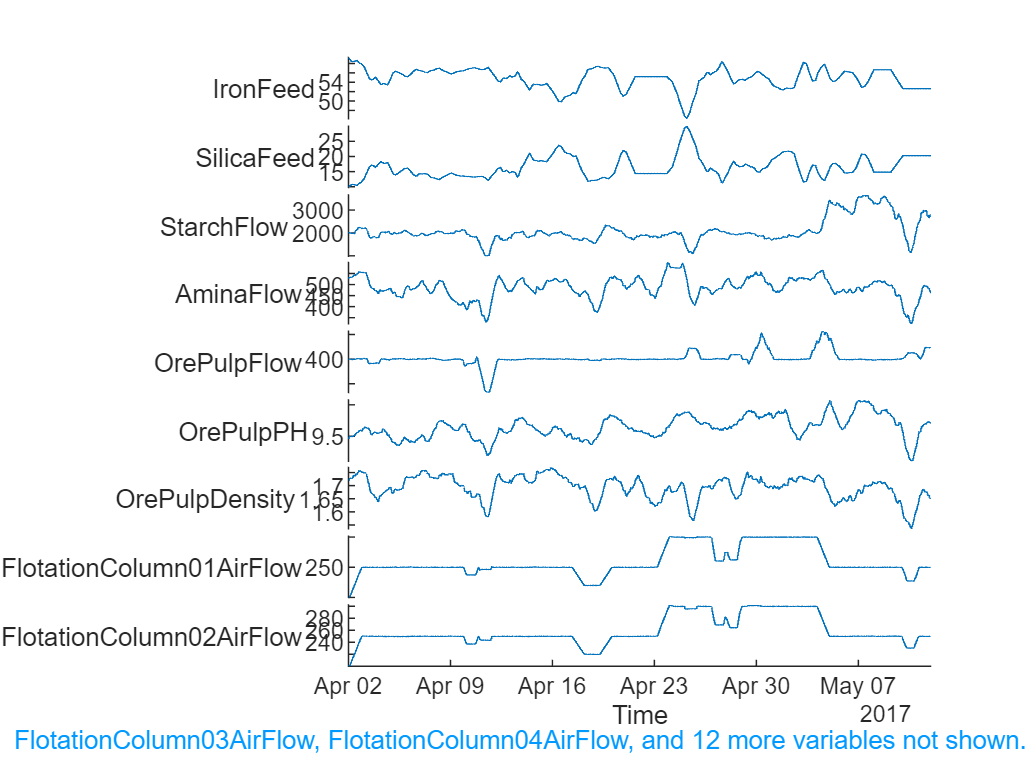

load range1.mat

origData = range1; % this is to get a bit shorter name for the data
origTime = origData.Time;
figure;
stackedplot(origData)

## Divide data

% Into predictor variables and predicted variable
model(1).X0 = range1{:,1:end-2};
model(1).Y0 = range1{:,end};

% check for missing values
sum(sum(isnan(model(1).X0)))

ans = 0

sum(isnan(model(1).Y0))

ans = 0


% Making division between calibration and validation
nobs    = length(model(1).Y0);

% We save 30% of the data for validation
part    = cvpartition(nobs, 'HoldOut', 0.3);
idxCal  = training(part);
idxVal  = test(part);


## Center and scale data

% We always center and scale the calibration part
% And apply the mean and standard deviation to the calibration

% X-side variables
% Center the mean to 0 and scale to the standard deviation of 1 the
% calibration set
[model(1).XCal, model(1).mu, model(1).sigma] = zscore(model(1).X0(idxCal, :)); 

% Apply the calibration center and standard deviation to the validation
% partition
model(1).XVal   = normalize(model(1).X0(idxVal,:), 'Center', model(1).mu, 'Scale', model(1).sigma);

% Y-side variables - We center it; a difference in the model is that the
% intercepts are not statistically significant if we center it
model(1).YCal   = model(1).Y0(idxCal) - mean(model(1).Y0(idxCal));
model(1).YVal   = model(1).Y0(idxVal) - mean(model(1).Y0(idxCal)); 


## Compute PCR

% Computing PCA

[modelPCA(1).P, modelPCA(1).T, modelPCA(1).latent, modelPCA(1).tsq, modelPCA(1).explained] = ...
    pca(model(1).XCal, 'Centered', false);

% Computing multiple regression 
% For each number of principal components, so we can evaluate the results
% afterwards

for i = 1:20
        % Model calibration

        % Linear regression coefficients for principal components
    modelPCR(i).betaPCs    = regress(model(1).YCal, modelPCA(1).T(:,1:i));
        % Transforming the regression coefficents for PCs in regression
        % coefficients for predictors
    modelPCR(i).betaVars   = modelPCA(1).P(:,1:i) * modelPCR(i).betaPCs;
        % Adding the intercept
    modelPCR(i).betaVars   = [mean(model(1).YCal) - mean(model(1).XCal)*modelPCR(i).betaVars; modelPCR(i).betaVars]; 

    
        % Calculating Yhat
    n = length(model(1).YCal);
    modelPCR(i).Yhat       = [ones(n,1) model(1).XCal] * modelPCR(i).betaVars;
 
        % Predicting the validation set
     m = length(model(1).YVal);
     modelPCR(i).YPred   = [ones(m,1) model(1).XVal] * modelPCR(i).betaVars;


     modelPCR(i).Yhat    = modelPCR(i).Yhat  + ones(n,1)*mean(model(1).Y0(idxCal));
     modelPCR(i).YPred   = modelPCR(i).YPred + ones(m,1)*mean(model(1).Y0(idxCal));


        % Calculating Prediction Errors
    modelPCR(i).TSS      = sum((model(1).Y0(idxCal) - mean(model(1).Y0(idxCal))).^2); 

        %R2
    modelPCR(i).RSS      = sum((model(1).Y0(idxCal) - modelPCR(i).Yhat).^2);
    modelPCR(i).R2       = 1 - modelPCR(i).RSS/modelPCR(i).TSS;

        %Q2
    modelPCR(i).PRESS    = sum((model(1).Y0(idxVal) - modelPCR(i).YPred).^2);
    modelPCR(i).Q2       = 1 - modelPCR(i).PRESS/modelPCR(i).TSS;

end


## Compute PLS


for i = 1:20
    [modelPLS(i).P , modelPLS(i).T, modelPLS(i).Q, modelPLS(i).U, ...
        modelPLS(i).beta, modelPLS(i).var, modelPLS(i).MSE, modelPLS(i).stats] = plsregress(model(1).XCal, model(1).YCal, i);
    % Calculate residuals 

        % Calculating Yhat
   n = length(model(1).YCal);
   modelPLS(i).Yhat       = [ones(n,1) model(1).XCal] * modelPLS(i).beta;
 
        % Predicting the validation set
   m = length(model(1).YVal);
   modelPLS(i).YPred    = [ones(m,1) model(1).XVal] * modelPLS(i).beta;

   modelPLS(i).TSS      = sum((model(1).YCal - mean(model(1).YCal)).^2); 

        %R2
    modelPLS(i).RSS      = sum((model(1).YCal - modelPLS(i).Yhat).^2);
    modelPLS(i).R2       = 1 - modelPLS(i).RSS/modelPLS(i).TSS;

        %Q2
    modelPLS(i).PRESS    = sum((model(1).YVal - modelPLS(i).YPred).^2);
    modelPLS(i).Q2       = 1 - modelPLS(i).PRESS/modelPLS(i).TSS;

end

## Evaluate model

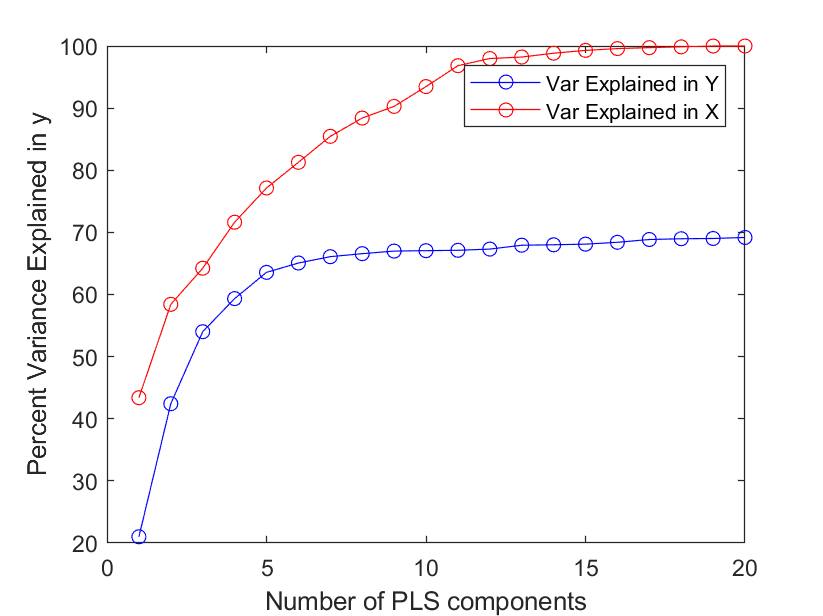

model(1).varNames = range1.Properties.VariableNames(1:end-1);

% Variance explained 
figure;
plot(1:20,cumsum(100*modelPLS(20).var(2,:)),'-bo');
hold on
plot(1:20,cumsum(100*modelPLS(20).var(1,:)),'-ro');
xlabel('Number of PLS components');
ylabel('Percent Variance Explained in y');
legend(["Var Explained in Y", "Var Explained in X"]);

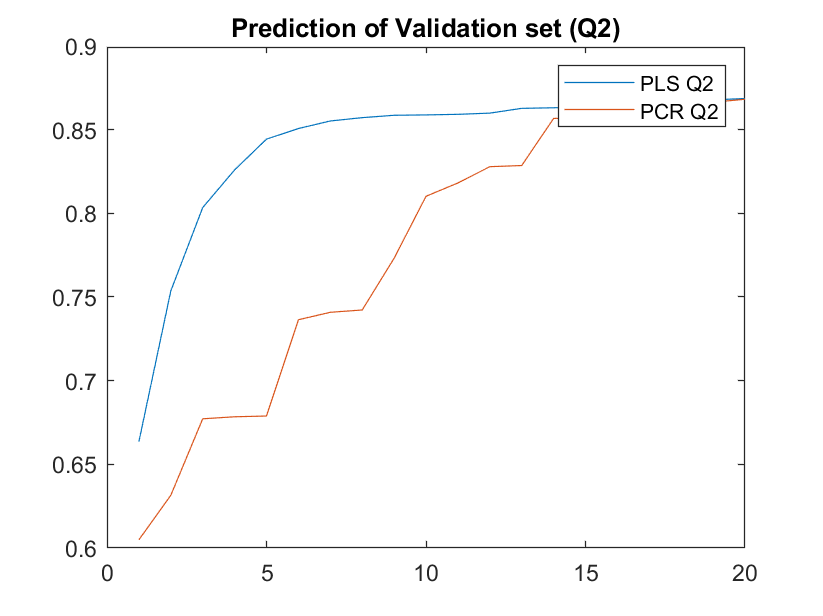


% Validation Q2
figure;
plot([modelPLS.Q2]);
hold on
plot([modelPCR.Q2]);
legend(["PLS Q2", "PCR Q2"]);
title("Prediction of Validation set (Q2)");

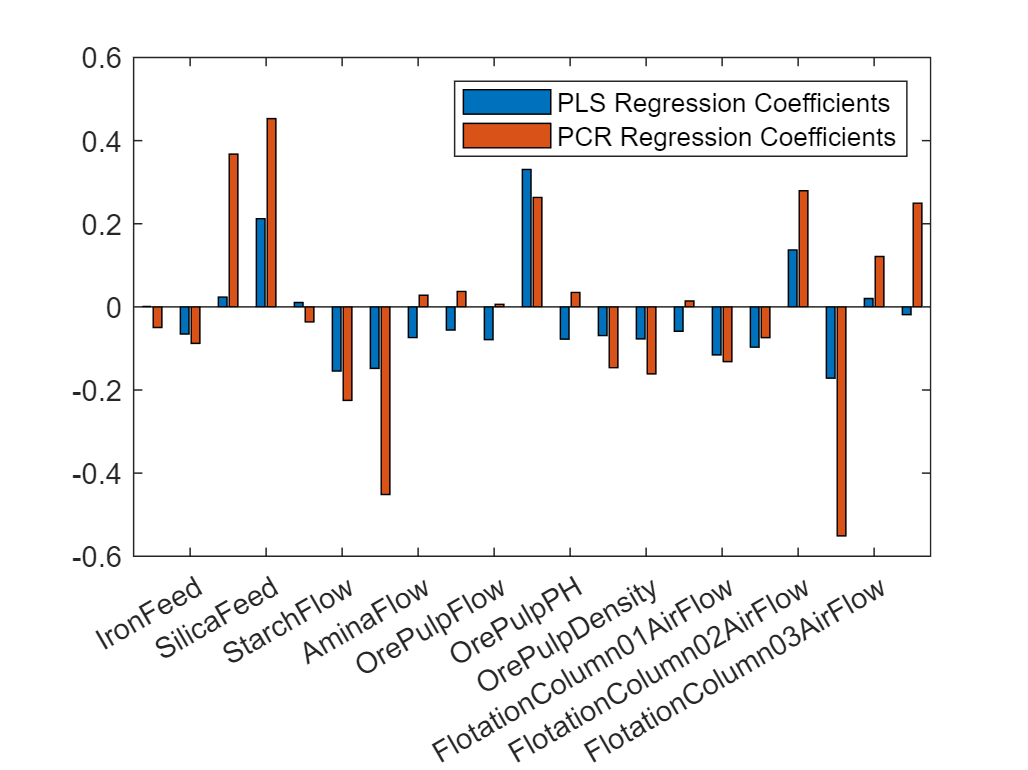




% Variable importance in prediction
figure;
betas = [modelPLS(3).beta(2:end), modelPCR(15).betaVars(2:end)];
bar(betas);
legend(["PLS Regression Coefficients", "PCR Regression Coefficients"]);
xticklabels(model(1).varNames);

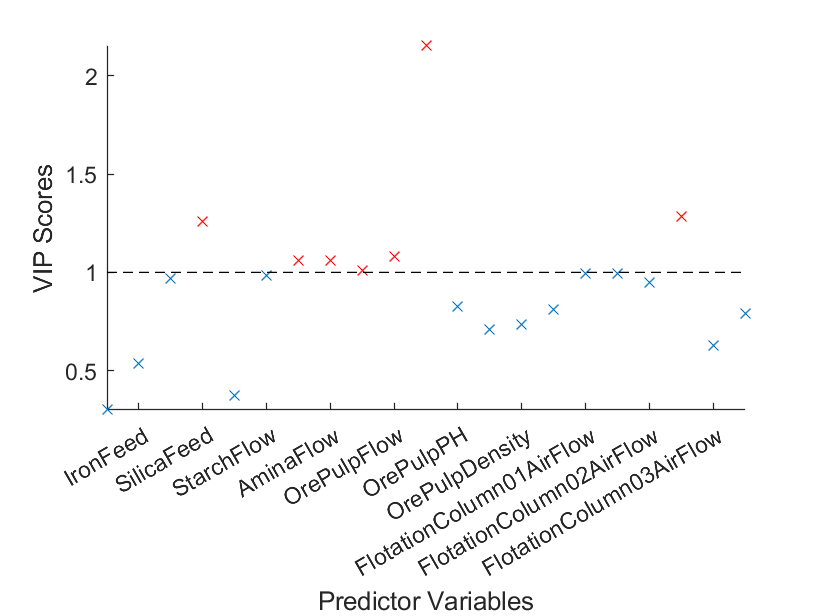


% VIP scores
% Uses the normalized PLS weights
modelPLS(3).W0 = modelPLS(3).stats.W ./ sqrt(sum(modelPLS(3).stats.W.^2,1));
p              = size(modelPLS(3).P, 1);
sumSq          = sum(modelPLS(3).T.^2,1).*sum(modelPLS(3).Q.^2,1);
vipScore       = sqrt(p* sum(sumSq.*(modelPLS(3).W0.^2),2) ./ sum(sumSq,2));
indVIP         = find(vipScore >= 1);
scatter(1:length(vipScore),vipScore,'x')
hold on
scatter(indVIP,vipScore(indVIP),'rx')
plot([1 length(vipScore)],[1 1],'--k')
hold off
axis tight
xlabel('Predictor Variables')
ylabel('VIP Scores')
xticklabels(model(1).varNames);